# Implementing, training and testing SciNet network

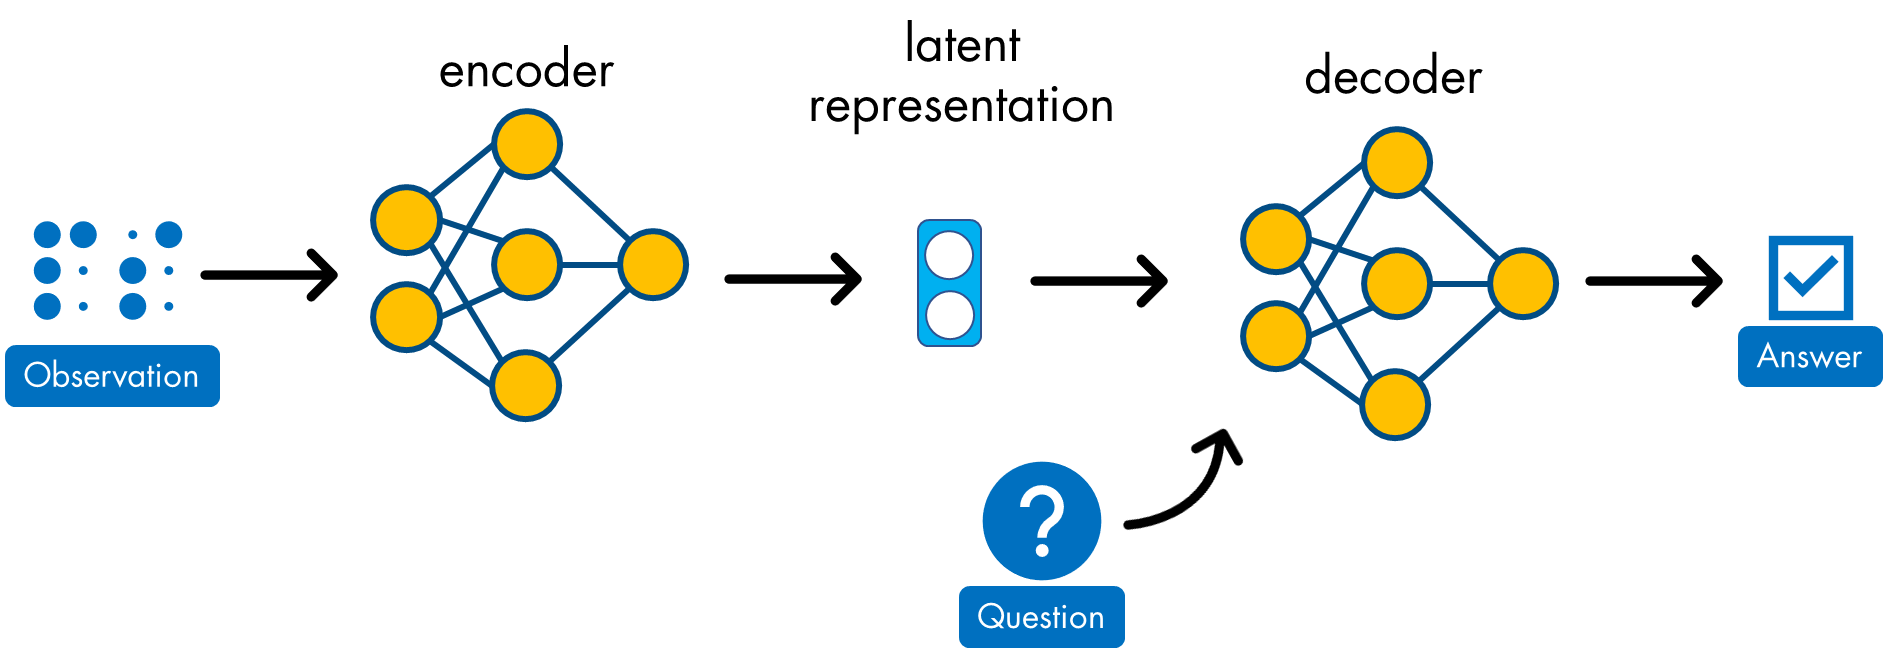

In this script, the SciNet network described in ***"Discovering physical concepts with neural networks" ****[*Iten, R., Metger, T., Wilming, H., Rio, L., & Renner, R. (2020). Discovering Physical Concepts with Neural Networks*. Phys. Rev. Lett., 124, 010508] is *implemented and trained.

SciNet attempts to formalize a simplified view of physical modelling thinking process and translate it into a neural network architecture.

Details can be found here: [1] [arXiv:1807.10300v3, Discovering physical concepts with neural networks](https://arxiv.org/abs/1807.10300v3).

Here we apply SciNet to a **damped linear oscillator**. This use case is also described in [1].

## Initialization

Close all figures, clear workspace, clear command window. For reproducibility, specify random seed generator.

close("all"); clear; clc; rng(0);

## Parameters

Define network and training parameters

NTimes = 50;
NSamples = 100000;
NTraining = 95000;

plotDataSample = true;
NPlotDataSample = 10;

latentDimension = 3; 

beta = 1e-3; % Appear in the beta-VAE cost function definition

% Physical parameters
physicalParameters.m = 1; %[kg]
physicalParameters.A0 = 1;% [m]
physicalParameters.delta0 = 0; % [rad]
physicalParameters.kMin = 5; % [kg/s^2]
physicalParameters.kMax = 10; % [kg/s^2]
physicalParameters.bMin = 0.5; % [kg/s]
physicalParameters.bMax = 1; % [kg/s]
Tfinal.observations = 5; % maximum of observations time in seconds --> time_observations in [0, Tfinal.observations]
Tfinal.answers = 10; % maximum of answers time in seconds --> time_answers in [0, Tfinal.answers]

## Generate and split data

Generate one-dimensional damped pendulum data then split into training and testing set.

observations = zeros(NTimes, 1, 1, NSamples);
answers = zeros(1, 1, 1, NSamples);
questions = zeros(1, 1, 1, NSamples);
[observations(:, 1, 1, :), observationsTime, answers(1, 1, 1, :), questions(1, 1, 1, :)] = ...
    generatePendulumData(NTimes, Tfinal, physicalParameters, NSamples);

% Plot NPlot random items 
if plotDataSample
    idxPlot = randi(NSamples, 1, NPlotDataSample);
    figure; plot(observationsTime, squeeze(observations(:, 1, 1, idxPlot)));
    hold("on");
    plot(squeeze(questions(1, 1, 1, idxPlot)), squeeze(answers(1, 1, 1, idxPlot)), "ro", "MarkerSize", 3);
end

% Split training and testing data
observationsTesting = observations(:, 1, 1, NTraining+1:end);
answersTesting = answers(1, 1, 1, NTraining+1:end);
questionsTesting = questions(1, 1, 1, NTraining+1:end);
observations(:, :, :, NTraining+1:end) = [];
answers(:, :, :, NTraining+1:end) = [];
questions(:, :, :, NTraining+1:end) = [];

% Convert to dlarray in 'SSCB' format
observations = dlarray(observations, "SSCB");
observationsTesting = dlarray(observationsTesting, "SSCB");
answers = dlarray(answers, "SSCB");
answersTesting = dlarray(answersTesting, "SSCB");
questions = dlarray(questions, "SSCB");
questionsTesting = dlarray(questionsTesting, "SSCB");

## Custom Variational Autoencoder (VAE) building blocks

The SciNet network is modified version of a VAE and has 2 parts (the encoder and the decoder).

The training process of the SciNet network can be described in several steps:

- **Encoding**: pass mini-batch of data through the encoder network and obtain the means and the variances in the latent space. The encoder takes an input and outputs a compressed representation (the encoding). For a VAE, this encoding representation is a vector of size `2*latent_dim`. This can be seen as a combination of 2 vectors of size `latent_dim: `one for the means $\mu$ and one for the variances $\sigma$. Those two vectors are then used to create the distribution to sample from. 

- **Sampling**: obtain the encodings by sampling in the distribution defined by means and variances (calling the function `sampleLatentSpace). ` The sampling step samples the mean and the variance vectors to create the final encoding to be passed to the decoder network. However, because backpropagation through a random sampling operation is not possible, a *reparameterization trick *is needed. This trick moves the random sampling operation to an auxiliary variable $\varepsilon$, which is then shifted by the mean $\mu_i$ and scaled by the standard deviation $\sigma_i$. The idea is that sampling from $N\left(\mu_i ,\sigma_i^2 \right)$ is the same as sampling from $\mu_i +\varepsilon \cdot \sigma_i$, where  $\varepsilon \sim N\left(0,1\right)$. The following figure depicts the *reparameterization trick* idea graphically. 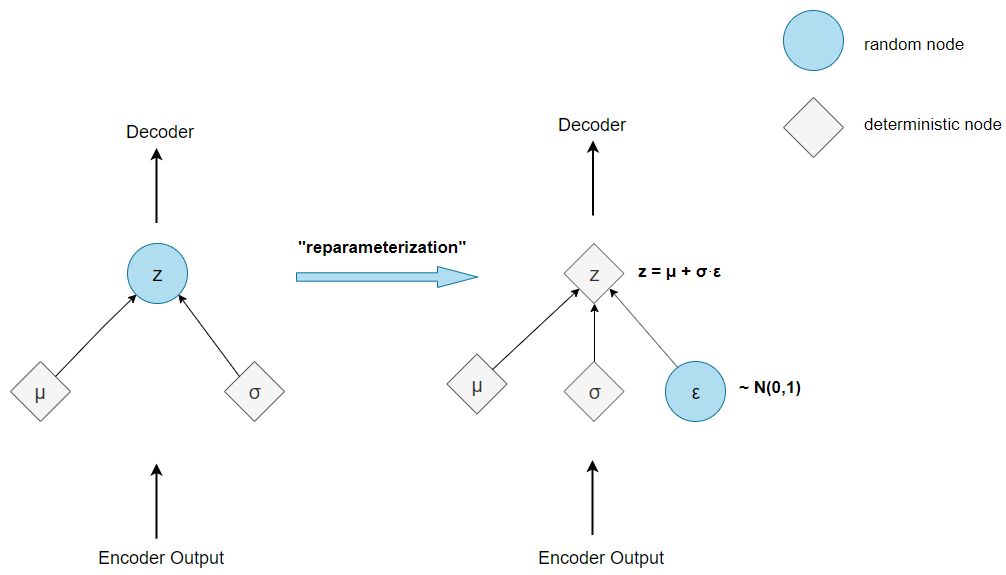

- **Decoding**: pass the "question" data and the encoding generated by the sampling step through the decoder network and obtain predicted answers. 

- **Loss computing**: obtain the loss by computing the $\beta -\textrm{VAE}$ cost. 

- **Gradient computing**: compute the gradients of the loss with respect to the learnable parameters of both networks by calling the `dlgradient` function. 

The $\beta -\textrm{VAE}$ cost function is defined as a sum of two separate loss terms: a reconstruction loss ($\textrm{MSE}$) and a KL loss or [Kullback–Leibler divergence](https://en.wikipedia.org/wiki/Kullback%E2%80%93Leibler_divergence) ($D_{\textrm{KL}}$). 

It is a modification of ELBO loss (used for classical VAE) with a multiplier $\beta \;\ge 0$.  If $\beta =1$ then, it is same as the ELBO Loss. With some assumptions, It can be expressed as follow: 


$$\beta -\textrm{VAE}=\underset{\textrm{MSE}}{\underbrace{{\left\|\bar{x} -x\right\|}_2^2 } } \;\;\underset{D_{\textrm{KL}} }{\;\;\;\underbrace{-\frac{\beta }{2}\;\left(\sum_i \log \left(\sigma {\;}_{i\;}^2 \right)-\mu {\;}_{i\;}^2 -\sigma {\;}_i^2 \right)} }$$


The *reconstruction loss* measures how close the decoder output is to the original input by using the mean-squared error ([MSE](https://www.mathworks.com/help/deeplearning/ref/mse.html)):

The *KL loss *measures the difference between two probability distributions. 

### Define Network architecture

In order to train the networks with a custom training loop and enable [automatic differentiation](https://www.mathworks.com/help/deeplearning/ug/deep-learning-with-automatic-differentiation-in-matlab.html), create them as [layer graphs](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layergraph.html) then convert them to [dlnetwork](https://www.mathworks.com/help/deeplearning/ref/dlnetwork.html) objects.

layersEncoder = [imageInputLayer([NTimes, 1], "Name", "Observations", "Normalization", "none");...
                fullyConnectedLayer(500, "Name", "fc_encoder_1"); ...
                eluLayer(1, "Name", "elu_encoder_1"); ...
                fullyConnectedLayer(100, "Name", "fc_encoder_2"); ...
                eluLayer(1, "Name", "elu_encoder_2"); ...
                fullyConnectedLayer(2*latentDimension, "Name", "Latent_Representations")]; % 2*latentDimension: (mu, sigma)
netEncoder = dlnetwork(layerGraph(layersEncoder)); 

layersDecoder = [imageInputLayer([latentDimension+1, 1], "Name", "Representations_and_question", "Normalization", "none"); % latentDimension+1: z, questions
                fullyConnectedLayer(100, "Name", "fc_decoder_1"); ...
                eluLayer(1, "Name", "elu_decoder_1"); ...
                fullyConnectedLayer(100, "Name", "fc_decoder_2"); ...
                eluLayer(1, "Name", "elu_decoder_2"); ...
                fullyConnectedLayer(1, "Name", "Answer")];
netDecoder = dlnetwork(layerGraph(layersDecoder));

### Define the model gradients function

The model gradients function is defined at the end of this example as the ScinetLossAndGradients helper function . This helper function takes the encoder and decoder [dlnetwork](https://www.mathworks.com/help/deeplearning/ref/dlnetwork.html) objects, a mini-batch of input data (`dlObservationsArray, dlQuestionsArray, dlAnswersArray`), and returns the gradients of the loss with respect to the learnable parameters in the networks. 

## Training loop

Implement the training process (if `doTraining` flag is set to true, if not load trained networks model)

doTraining = true;

if ~doTraining
    % Load trained encoder, trained Decoder and latent space dimension
    load("results.mat", "netEncoder", "netDecoder", "latentDimension");
else
    miniBatchSize = 500;
    learningRate = 1e-3;
    numEpochs = 1000;
    
    trailingAvgEncoder = [];
    trailingAvgSqEncoder = [];
    trailingAvgDecoder = [];
    trailingAvgSqDecoder = [];
    gradDecay = 0.9;
    gradDecaySq = 0.99;
    
    progressLineHandle = createTrainingProgressPlot();
    
    numMiniBatches = round(NTraining / miniBatchSize);
    for ie = 1 : numEpochs
        
        for ib = 1 : numMiniBatches
            
            % Extract data corresponding to this minibatch
            theseObservations = observations(:, :, :, (ib-1)*miniBatchSize+1:ib*miniBatchSize);
            theseQuestions = questions(:, :, :, (ib-1)*miniBatchSize+1:ib*miniBatchSize);
            theseAnswers = answers(:, :, :, (ib-1)*miniBatchSize+1:ib*miniBatchSize);
            
            % Evaluate gradients and loss for this minibatch
            [gradientsEncoder, gradientsDecoder, loss] = ...
                dlfeval(@ScinetLossAndGradients, netEncoder, netDecoder, ...
                theseObservations, theseQuestions, theseAnswers, ...
                latentDimension, beta, miniBatchSize);
            loss = double(extractdata(loss));
            
            % Update iteration number for adam
            adamIteration = (ie-1)*numMiniBatches + ib;
            
            % Update encoder learnables
            [netEncoder, trailingAvgEncoder, trailingAvgSqEncoder] = ...
                adamupdate(netEncoder, gradientsEncoder, ...
                trailingAvgEncoder, trailingAvgSqEncoder, adamIteration, ...
                learningRate, gradDecay, gradDecaySq);
            
            % Update decoder learnables
            [netDecoder, trailingAvgDecoder, trailingAvgSqDecoder] = ...
                adamupdate(netDecoder, gradientsDecoder, ...
                trailingAvgDecoder, trailingAvgSqDecoder, adamIteration, ...
                learningRate, gradDecay, gradDecaySq);
    
            % Update the training loss progress plot.
            addpoints(progressLineHandle, adamIteration, log10(loss));
            drawnow;

        end
        
    end

end

## Testing decoder prediction performance

Prediction on testing data

NTesting = NSamples - NTraining;
predictedLatentRepresentation = forwardEncoder(netEncoder, observationsTesting);
[predictedZ, ~, ~] = sampleLatentSpace(predictedLatentRepresentation, latentDimension, NTesting);
predictedAnswers = forwardDecoder(netDecoder, predictedZ, questionsTesting);

% Jacknife plot
answersTesting = double(extractdata(answersTesting(:)));
questionsTesting = double(extractdata(questionsTesting(:)));
predictedAnswers = double(extractdata(predictedAnswers(:)));

figure
scatter(predictedAnswers, answersTesting);
ylabel("answersTesting");
xlabel("predictedAnswers");
title("Actual vs jackknife predicted");
grid("on");

figure; plot(questionsTesting, answersTesting, "bo");
hold("on");
plot(questionsTesting, predictedAnswers, "r*");
grid("on");
legend("answersTesting", "predictedAnswers");
xlabel("Time (questionsTesting)");
ylabel("Displacement")

## Saving all results

if doTraining
    save("../results/results");
end

## Helper functions

### Model Gradients function

The `ScinetLossAndGradients` function takes the encoder and decoder [dlnetwork](https://www.mathworks.com/help/deeplearning/ref/dlnetwork.html) objects, a mini-batch of input data (`dlObservationsArray, dlQuestionsArray, dlAnswersArray`), and returns the gradients of the loss with respect to the learnable parameters in the networks. The function performs several operations:

- **Encoding**: pass mini-batch of data through the encoder network and obtain the means and the variances in the latent space.

- **Sampling**: obtain the encodings by sampling in the distribution defined by means and variances (calling the function `sampleLatentSpace). ` 

- **Decoding**: pass the "question" data and the encoding generated by the sampling step through the decoder network and obtain predicted answers. 

- **Loss computing**: determine the loss by computing the $\beta -\textrm{VAE}$ cost. 

- **Gradient computing**: compute the gradients of the loss with respect to the learnable parameters of both networks by calling the `dlgradient` function. 

function [gradientsEncoder, gradientsDecoder, loss] = ...
    ScinetLossAndGradients(netEncoder, netDecoder, dlObservationsArray, dlQuestionsArray, dlAnswersArray, latentDimension, beta, miniBatchSize)

% Forward pass for encoder to predict mean and variance in the latent space
latentRepresentation = forwardEncoder(netEncoder, dlObservationsArray);

% Sampling in the latent space
[z, mu, sigma] = sampleLatentSpace(latentRepresentation, latentDimension, miniBatchSize);

% Foward pass for decoder given samples and questions
predictedAnswers = forwardDecoder(netDecoder, z, dlQuestionsArray);

% Compute first term of Beta-VAE cost: MSE
MSE = sum( (dlAnswersArray - predictedAnswers).^2, 1 );

% Compute second term of Beta-VAE cost: KL 
KL = -beta/2 * sum( log(sigma.^2) - mu.^2 - sigma.^2, 1 );

% Loss as a mean across the minibatch of the sums
loss = squeeze( mean(MSE + KL, 4) );

% Return gradients
gradientsEncoder = dlgradient(loss, netEncoder.Learnables);
gradientsDecoder = dlgradient(loss, netDecoder.Learnables);

end

### Create a figure to visualize learning curve progression

function lineHandle = createTrainingProgressPlot()

% Open plot
trainingPlot = figure;
trainingPlot.Position(3) = 16/9*trainingPlot.Position(4);
trainingPlot.Visible = "on";

% Add gridded axes
trainingPlotAxes = axes("Parent", trainingPlot);
grid(trainingPlotAxes, "on");

% Add animated line
lineHandle = animatedline(trainingPlotAxes);
xlabel(trainingPlotAxes, "Iteration" );
ylabel(trainingPlotAxes, "Log10(Loss)" );
title(trainingPlotAxes, "Log10(Loss) against Iteration");

end

Copyright 2021 The MathWorks, Inc.